Both time stepping methods solved $\mathbf{u}'=\mathbf{D}_{xx}\mathbf{u}$, for the matrix

m = 40;  [~,~,Dxx] = diffper(m,[0,1]);

The eigenvalues of this martrix are real and negative.

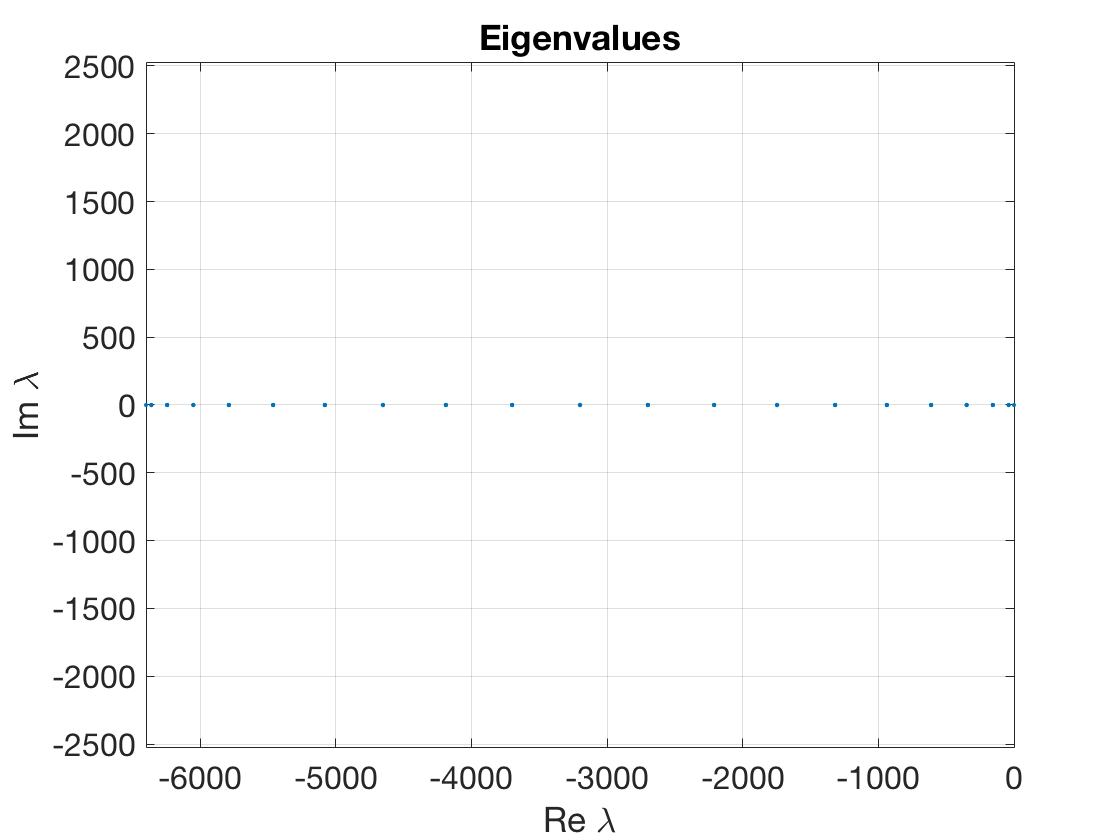

lambda = eig(Dxx);
plot(real(lambda),imag(lambda),'.')
axis equal, grid on   % ignore this line
xlabel('Re \lambda'),  ylabel('Im \lambda')   % ignore this line
title('Eigenvalues')   % ignore this line

The Euler method is absolutely stable in the region $|\zeta+1| \le 1$ in the complex plane:

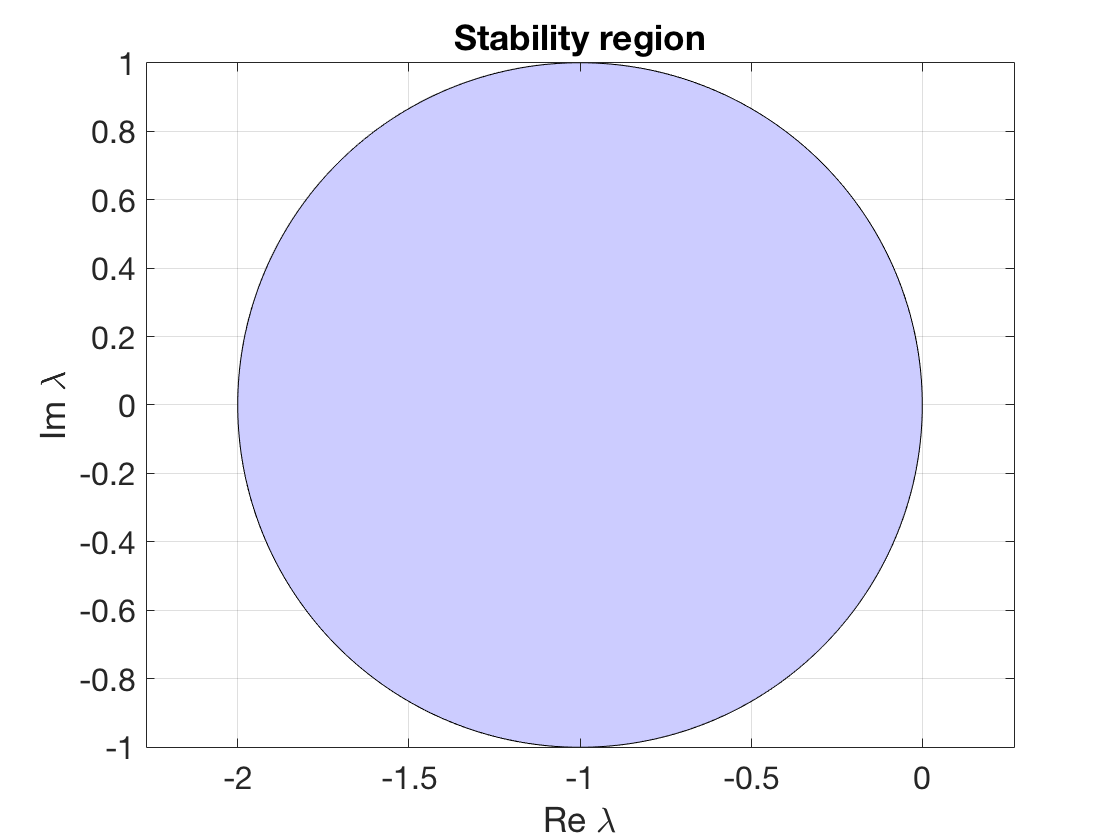

phi = linspace(0,2*pi,361);
z = exp(1i*phi) - 1;   % unit circle shifted to the left by 1
fill(real(z),imag(z),[.8 .8 1])
axis equal, grid on   % ignore this line
xlabel('Re \lambda'),  ylabel('Im \lambda')   % ignore this line
title('Stability region')   % ignore this line

In order to get inside this region, we have to find $\tau$ such that $\lambda \tau > -2$ for all eigenvalues $\lambda$. This is an *upper* bound on $\tau$. 

lambda_min = min(lambda)

lambda_min =    -6400       


max_tau = -2 / lambda_min

max_tau =        1/3200  


Here we plot the resulting values of $\zeta=\lambda \tau$. 

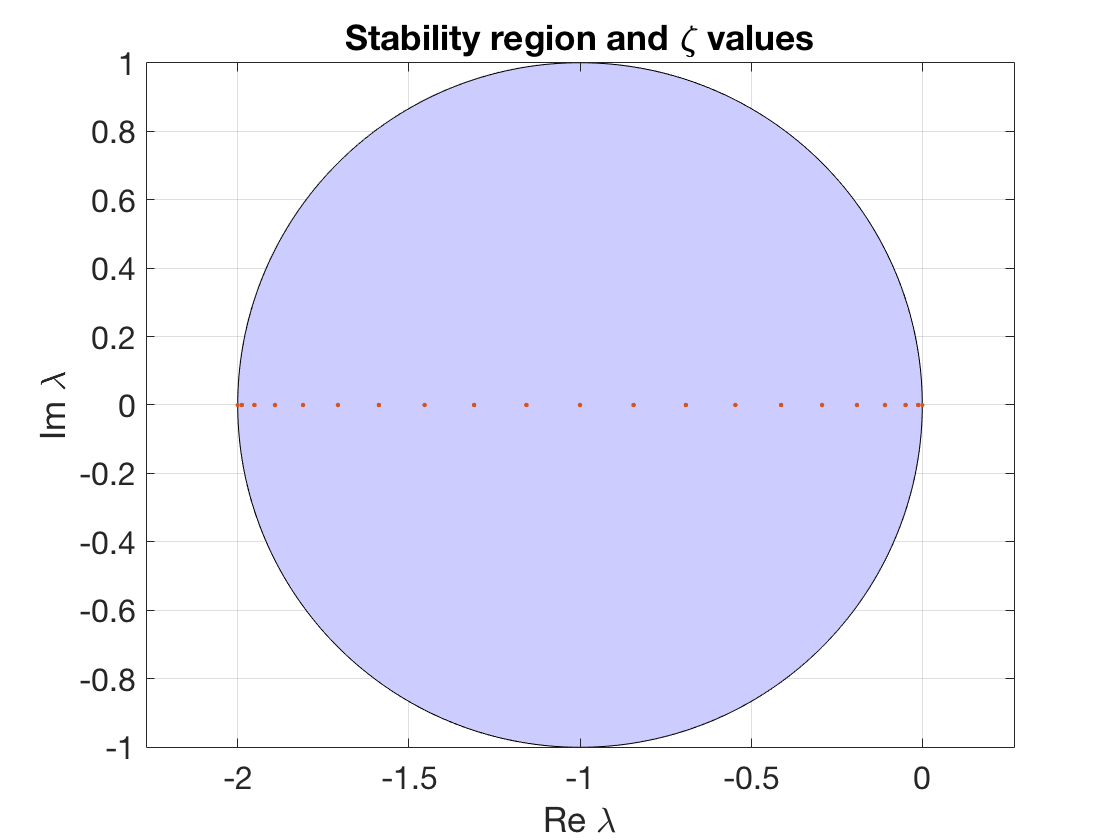

zeta = lambda*max_tau;
hold on
plot(real(zeta),imag(zeta),'.')
title('Stability region and \zeta values')   % ignore this line

In backward Euler, the region is $|\zeta-1|\ge 1$. Because they are all on the negative real axis, all of the $\zeta$ values will fit no matter what $\tau$ is chosen.

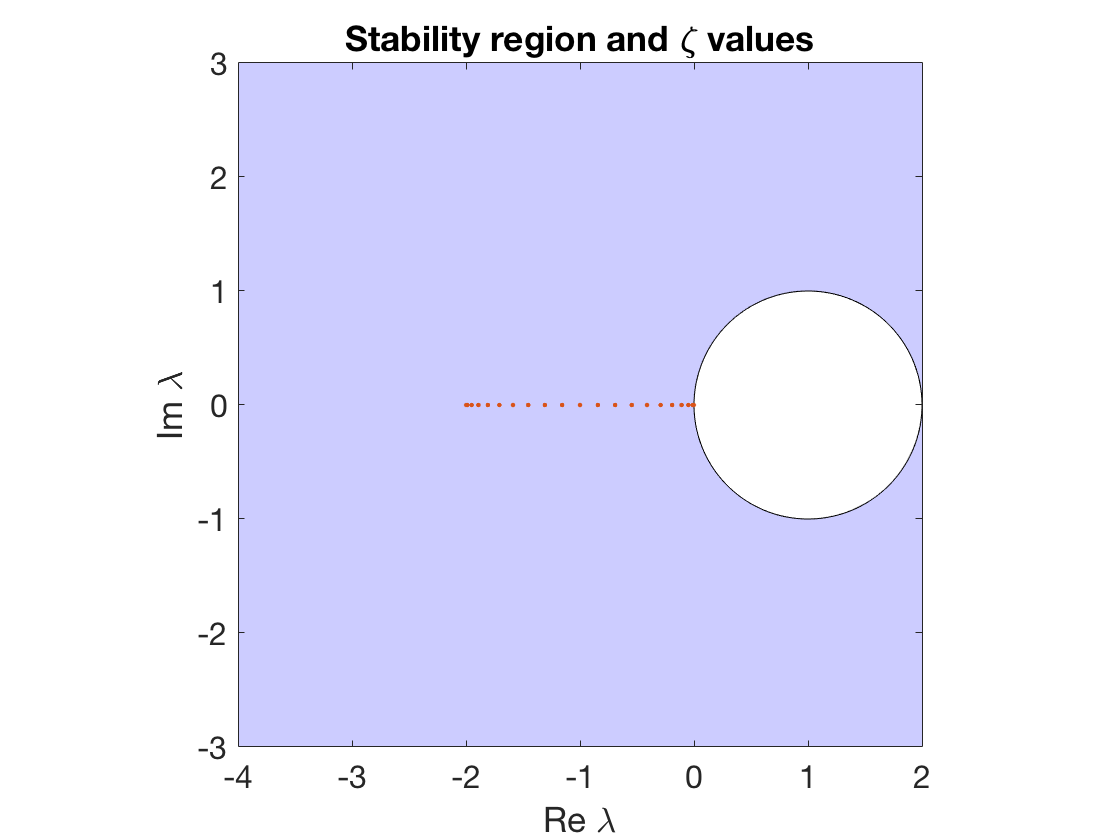

clf,  fill([-6 6 6 -6],[-6 -6 6 6],[.8 .8 1]),  hold on
z = exp(1i*phi) + 1;   % unit circle shifted right by 1
fill(real(z),imag(z),'w')
plot(real(zeta),imag(zeta),'.')
axis equal, axis([-4 2 -3 3]), grid on   % ignore this line
xlabel('Re \lambda'),  ylabel('Im \lambda')   % ignore this line
title('Stability region and \zeta values')   % ignore this line